# **Análise e Modelagem de Sistemas Dinâmicos - 2023/2**

## Nome: Thiago Felippe Neitzke Lahass

## Data limite para entrega: 06/09/2023

### A entrega deverá ser feita pelo Google ClassRoom

# Trabalho 1 - Modelagem de Sistemas

I = 10;          % Seu número I
init_t1(I);     % Define as variaveis do modelo
datetime('now')

ans = datetime
   06-Sep-2023 00:10:23


## Modelagem de Turbina-Gerador Eólico

A figura a seguir mostra um sistema turbina-gerador eólico usado para transformar energia mecânica em energia elétrica. Para esse problema, assume-se que a inércia da turbina $J_1$ e a do gerador $J_2$ são conectadas rigidamente às suas engrenagens no trem de engrenagens. O vento gera um torques aerodinâmico $T_{\textrm{aero}}$ na turbina, fazendo o gerador rotacionar. O giro do rotor do gerador sobre o campo magnético produz uma força contra-eletromotriz no rotor, e consequentemente um torque $T_{\textrm{ger}}$. 

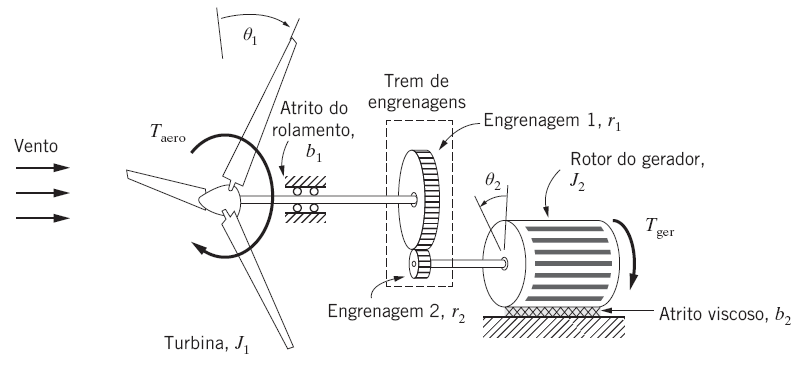

Os parâmetros do sistema turbina eólica-gerador são:

Momento de inércia da turbina $J_1$ [$\textrm{kg}\ldotp m^2$]

Momento de inércia do gerador $J_2$ [$\textrm{kg}\ldotp m^2$]

Raio da turbina (da extremidade das pás ao cubo) $R$ [$m$]

Coeficiente de atrito da turbina $b_1$ [$N\cdot m\cdot s/\textrm{rad}$]

Coeficiente de atrito do gerador $b_2$ [$N\cdot m\cdot s/\textrm{rad}$]

Relação de transmissão $N=r_2 /r_1$

**Funções úteis do Matlab:** tf, step, stepDataOptions, lsim, figure, plot, grid, yyaxis, title, xlabel, ylabel, sprintf, linspace.

### 1.1 Assumindo como entrada do sistema um torque ${\mathit{\mathbf{T}}}_1 (\mathit{\mathbf{t}})={\mathit{\mathbf{T}}}_{\mathbf{a}\mathbf{e}\mathbf{r}\mathbf{o}} (\mathit{\mathbf{t}})-\frac{1}{\mathit{\mathbf{N}}}{\mathit{\mathbf{T}}}_{\mathbf{g}\mathbf{e}\mathbf{r}} (\mathit{\mathbf{t}})$, apresente o modelo matemático dinâmico desse sistema em termos da velocidade angular da turbina ($\omega_1$).

O torque $T_{\textrm{E1}} \left(t\right)$ resultante no eixo 1 é:

$T_{\textrm{E1}} \left(t\right)=T_{\textrm{aero}} \left(t\right)-J_1 \ddot{\theta_{1\;} } \left(t\right)-b_1 \dot{\theta_1 } \left(t\right)$         (1).

Já para o eixo 2 temos:

$T_{\textrm{E2}} \left(t\right)=J_2 \ddot{\theta_2 } \left(t\right)+b_2 \dot{\theta_2 } \left(t\right)+T_{\textrm{ger}} \left(t\right)$           (2).

Pela relação de engrenagens, temos:

$\frac{T_{\textrm{E2}} \left(t\right)}{T_{\textrm{E1}} \left(t\right)}=\frac{\theta_1 }{\theta_2 }=\frac{\omega_1 }{\omega_2 }=\frac{r_2 }{r_1 }=N$                      (3).

Substituindo (1) e (2) em (3), obtemos:


$$\left(T_{\textrm{aero}} \left(t\right)-J_1 \ddot{\theta_{1\;} } \left(t\right)-b_1 \dot{\theta_1 } \left(t\right)\right)N=J_2 \ddot{\theta_2 } \left(t\right)+b_2 \dot{\theta_2 } \left(t\right)+T_{\textrm{ger}} \left(t\right)\Rightarrow$$



$$\Rightarrow T_{\textrm{aero}} \left(t\right)-J_1 \ddot{\theta_{1\;} } \left(t\right)-b_1 \dot{\theta_1 } \left(t\right)=\frac{J_2 \ddot{\theta_2 } \left(t\right)+b_2 \dot{\theta_2 } \left(t\right)+T_{\textrm{ger}} \left(t\right)}{N}\Rightarrow$$



$$\Rightarrow T_{\textrm{aero}} \left(t\right)-J_1 \ddot{\theta_{1\;} } \left(t\right)-b_1 \dot{\theta_1 } \left(t\right)=\frac{J_2 \ddot{\theta_2 } \left(t\right)+b_2 \dot{\theta_2 } \left(t\right)}{N}+\frac{T_{\textrm{ger}} \left(t\right)}{N}\Rightarrow$$



$$\Rightarrow T_{\textrm{aero}} \left(t\right)-\frac{T_{\textrm{ger}} \left(t\right)}{N}=\frac{J_2 \ddot{\theta_2 } \left(t\right)+b_2 \dot{\theta_2 } \left(t\right)}{N}+J_1 \ddot{\theta_{1\;} } \left(t\right)+b_1 \dot{\theta_1 } \left(t\right)$$


Como $T_1 (t)=T_{\mathrm{a}\mathrm{e}\mathrm{r}\mathrm{o}} (t)-\frac{1}{N}T_{\mathrm{g}\mathrm{e}\mathrm{r}} (t)$, então:

$T_1 (t)=\frac{J_2 \ddot{\theta_2 } \left(t\right)+b_2 \dot{\theta_2 } \left(t\right)}{N}+J_1 \ddot{\theta_{1\;} } \left(t\right)+b_1 \dot{\theta_1 } \left(t\right)$.        (4)

Como por (3) temos $\theta_2 \left(t\right)=\frac{\theta_1 \left(t\right)}{N}$, e $\dot{\theta_1 } \left(t\right)=\omega_1 \left(t\right)$, substituindo em (4) ficamos com:


$$T_1 (t)=\frac{J_2 \frac{\ddot{\theta_1 } \left(t\right)}{N}+b_2 \frac{\dot{\theta_1 } \left(t\right)}{N}}{N}+J_1 \ddot{\theta_{1\;} } \left(t\right)+b_1 \dot{\theta_1 } \left(t\right)\Rightarrow$$



$${\Rightarrow \;T}_1 (t)=\frac{J_2 \dot{\omega_1 } \left(t\right)+b_2 \omega_1 \left(t\right)}{N^2 }+J_1 \dot{\omega_1 } \left(t\right)+b_1 \omega_1 \left(t\right)\Rightarrow$$


${\Rightarrow \;\mathit{\mathbf{T}}}_1 (\mathit{\mathbf{t}})=\left({\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }\right)\dot{\omega_1 } \left(\mathit{\mathbf{t}}\right)+\left({\mathit{\mathbf{b}}}_1 +\frac{{\mathit{\mathbf{b}}}_2 }{{\mathit{\mathbf{N}}}^2 }\right)\omega_1 \left(\mathit{\mathbf{t}}\right)$         (5).

### 1.2 Apresente a Função de Transferência ${\mathit{\mathbf{G}}}_1 (\mathit{\mathbf{s}})=\frac{\Omega_1 (\mathit{\mathbf{s}})}{{\mathit{\mathbf{T}}}_1 (\mathit{\mathbf{s}})}$.

Aplicando Laplace com condições iniciais nulas na equação (5), de forma direta obtemos:


$${\;T}_1 (s)=s\left(J_1 +\frac{J_2 }{N^2 }\right)\Omega_1 \left(s\right)+\left(b_1 +\frac{b_2 }{N^2 }\right)\Omega_1 \left(s\right)\Rightarrow$$


${\;T}_1 (s)=\Omega_1 \left(s\right)\left\lbrace s\left(J_1 +\frac{J_2 }{N^2 }\right)+\left(b_1 +\frac{b_2 }{N^2 }\right)\right\rbrace$                   (6).

Portanto:

${\mathit{\mathbf{G}}}_1 (\mathit{\mathbf{s}})=\frac{\Omega_1 (\mathit{\mathbf{s}})}{{\mathit{\mathbf{T}}}_1 (\mathit{\mathbf{s}})}=\frac{1}{\mathit{\mathbf{s}}\left({\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }\right)+\left({\mathit{\mathbf{b}}}_1 +\frac{{\mathit{\mathbf{b}}}_2 }{{\mathit{\mathbf{N}}}^2 }\right)}=\frac{\frac{1}{{\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }}}{\mathit{\mathbf{s}}+\frac{{\mathit{\mathbf{b}}}_1 +\frac{{\mathit{\mathbf{b}}}_2 }{{\mathit{\mathbf{N}}}^2 }}{{\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }}}$     (7).

### 1.3 Considere que o torque aerodinâmico é dado por:

### $T_{\textrm{aero}} \left(t\right)=\frac{1}{2}\rho \pi R^3 C_t V_v \left(t\right)\;\;\left\lbrack N\cdot m\right\rbrack$ ,

### que é função da massa específica do ar $\rho$ (em $\textrm{kg}/m^3$), do raio da turbina $R$ (em $m$), da velocidade do vento $V_v$ (em $m/s$), e do coeficiente de torque $C_t \ldotp$ 

### E que o torque gerado pela força contra-eletromotriz é dado por:

### $T_{\textrm{ger}} \left(t\right)=158,7\omega_2 \left(t\right)\;\;\;\left\lbrack N\cdot m\right\rbrack$ .

### Apresente a Função de Transferência ${\mathit{\mathbf{G}}}_v (\mathit{\mathbf{s}})=\frac{\Omega_1 (\mathit{\mathbf{s}})}{{\mathit{\mathbf{V}}}_{\mathbf{v}} (\mathit{\mathbf{s}})}$.

Partindo da equação (5) e tendo que $T_1 (t)=T_{\mathrm{a}\mathrm{e}\mathrm{r}\mathrm{o}} (t)-\frac{1}{N}T_{\mathrm{g}\mathrm{e}\mathrm{r}} (t)$, então:

$T_1 (t)=T_{\mathrm{a}\mathrm{e}\mathrm{r}\mathrm{o}} (t)-\frac{1}{N}T_{\mathrm{g}\mathrm{e}\mathrm{r}} (t)=\left(J_1 +\frac{J_2 }{N^2 }\right)\dot{\omega_1 } \left(t\right)+\left(b_1 +\frac{b_2 }{N^2 }\right)\omega_1 \left(t\right)$,

substituindo as expressões dadas para $\left.T_{\mathrm{a}\mathrm{e}\mathrm{r}\mathrm{o}} (t\right)$ e $T_{\mathrm{g}\mathrm{e}\mathrm{r}} (t)$, obtemos:

$\frac{1}{2}\rho \pi R^3 C_t V_v \left(t\right)-\frac{1}{N}158,7\omega_2 \left(t\right)=\left(J_1 +\frac{J_2 }{N^2 }\right)\dot{\omega_1 } \left(t\right)+\left(b_1 +\frac{b_2 }{N^2 }\right)\omega_1 \left(t\right)$,

mas por (3) $\omega_2 =\frac{\omega_1 }{N}$, logo:


$$\frac{1}{2}\rho \pi R^3 C_t V_v \left(t\right)-\frac{1}{N}158,7\frac{\omega_1 }{N}=\left(J_1 +\frac{J_2 }{N^2 }\right)\dot{\omega_1 } \left(t\right)+\left(b_1 +\frac{b_2 }{N^2 }\right)\omega_1 \left(t\right)\Rightarrow$$



$$\Rightarrow \frac{1}{2}\rho \pi R^3 C_t V_v \left(t\right)-\frac{158,7\omega_1 }{N^2 }=\left(J_1 +\frac{J_2 }{N^2 }\right)\dot{\omega_1 } \left(t\right)+\left(b_1 +\frac{b_2 }{N^2 }\right)\omega_1 \left(t\right)\Rightarrow$$



$$\Rightarrow \frac{1}{2}\rho \pi R^3 C_t V_v \left(t\right)=\left(J_1 +\frac{J_2 }{N^2 }\right)\dot{\omega_1 } \left(t\right)+\left(b_1 +\frac{b_2 +158,7}{N^2 }\right)\omega_1 \left(t\right)\Rightarrow$$


$\Rightarrow V_v \left(t\right)=\frac{\left(J_1 +\frac{J_2 }{N^2 }\right)\dot{\omega_1 } \left(t\right)+\left(b_1 +\frac{b_2 +158,7}{N^2 }\right)\omega_1 \left(t\right)}{\frac{1}{2}\rho \pi R^3 C_t }$        (8).

Aplicando Laplace com condições iniciais nulas na equação (8), temos:


$$V_v \left(s\right)=\frac{s\left(J_1 +\frac{J_2 }{N^2 }\right)\Omega_1 \left(s\right)+\left(b_1 +\frac{b_2 +158,7}{N^2 }\right)\Omega_1 \left(s\right)}{\frac{1}{2}\rho \pi R^3 C_t }\Rightarrow$$


${\Rightarrow \;V}_v \left(s\right)=\Omega_1 \left(s\right)\frac{s\left(J_1 +\frac{J_2 }{N^2 }\right)+\left(b_1 +\frac{b_2 +158,7}{N^2 }\right)}{\frac{1}{2}\rho \pi R^3 C_t }$            (9).

Portanto:

${\mathit{\mathbf{G}}}_{\mathit{\mathbf{v}}} (\mathit{\mathbf{s}})=\frac{\Omega_1 (\mathit{\mathbf{s}})}{{\mathit{\mathbf{V}}}_{\mathbf{v}} (\mathit{\mathbf{s}})}=\frac{\frac{1}{2}\rho \pi {\mathit{\mathbf{R}}}^3 {\mathit{\mathbf{C}}}_{\mathit{\mathbf{t}}} }{\mathit{\mathbf{s}}\left({\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }\right)+\left({\mathit{\mathbf{b}}}_1 +\frac{{\mathit{\mathbf{b}}}_2 +158,7}{{\mathit{\mathbf{N}}}^2 }\right)}=\frac{\frac{\frac{1}{2}\rho \pi {\mathit{\mathbf{R}}}^3 {\mathit{\mathbf{C}}}_{\mathit{\mathbf{t}}} }{{\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }}}{\mathit{\mathbf{s}}+\frac{{\mathit{\mathbf{b}}}_1 +\frac{{\mathit{\mathbf{b}}}_2 +158,7}{{\mathit{\mathbf{N}}}^2 }}{{\mathit{\mathbf{J}}}_1 +\frac{{\mathit{\mathbf{J}}}_2 }{{\mathit{\mathbf{N}}}^2 }}}$        (10).

### 1.4 Mostre as Funções de Transferência ($G_1 \left(s\right)$ e $G_v \left(s\right)$) com os valores referentes ao seu número I.

% comandos do matlab
close all;
N = r2/r1;
s = tf('s'); %variável de Laplace
G1 = (1/(J1+J2/(N^2)))/(s + (b1+b2/(N^2))/(J1+J2/(N^2)))

G1 =
 
    9.067e-08
  -------------
  s + 0.0001163
 
Continuous-time transfer function.
Model Properties


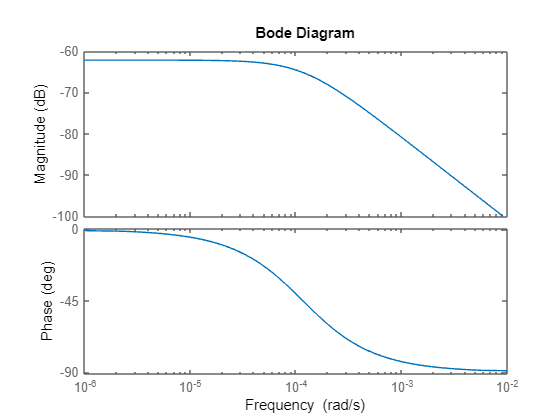

bode(G1);

Gv = (((1/2)*ro*pi*(R^3)*Ct)/(J1+J2/(N^2)))/(s + (b1+(b2+158.7)/(N^2))/(J1+J2/(N^2)))

Gv =
 
  0.0008375
  ----------
  s + 0.0249
 
Continuous-time transfer function.
Model Properties


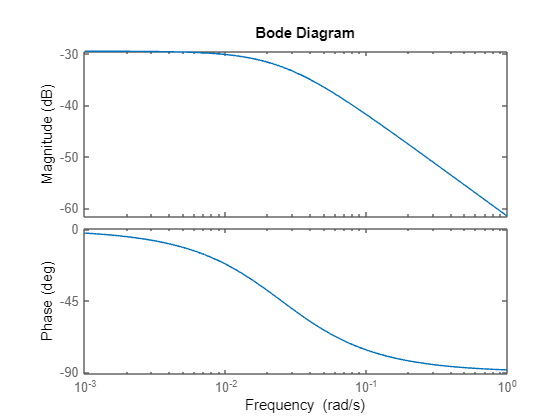

bode(Gv);

### 1.5 Plote a resposta de $G_1 \left(s\right)$ para $T_1 \left(t\right)=1\left\lbrack N\cdot m\right\rbrack$.

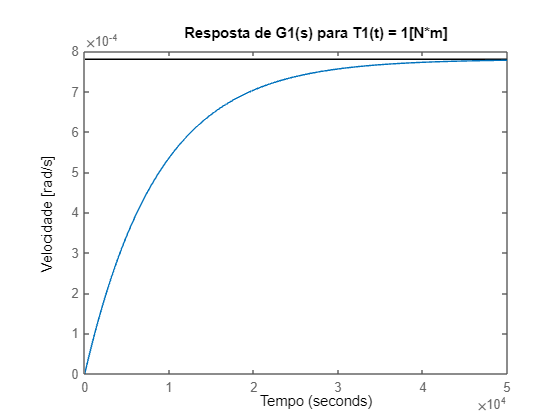

% comandos do matlab
figure,  step(G1); % Resposta ao degrau de 1 N.m (1(t))
xlabel('Tempo'),ylabel('Velocidade [rad/s]'),
title('Resposta de G1(s) para T1(t) = 1[N*m]');

### 1.6 Plote a resposta de $G_v \left(s\right)$ para $V_v \left(t\right)=1\left\lbrack m/s\right\rbrack$.

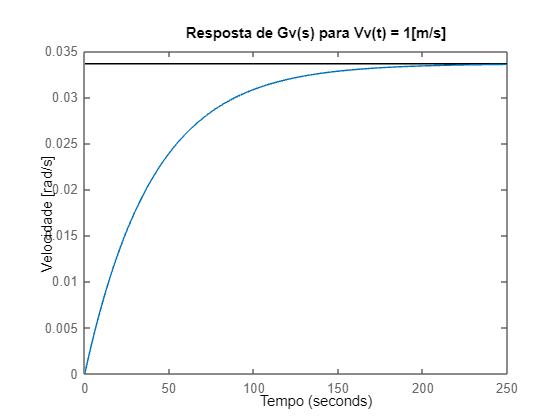

% comandos do matlab
figure,  step(Gv); % Resposta ao degrau de 1 m/s (1(t))
xlabel('Tempo'),ylabel('Velocidade [rad/s]'),
title('Resposta de Gv(s) para Vv(t) = 1[m/s]');

### 1.7 Faça os gráficos da velocidade angular da turbina ($\omega_1 \left(t\right)$) e do gerador ($\omega_2 \left(t\right)$) com o valor de $V_v \left(t\right)$referente ao seu número I.

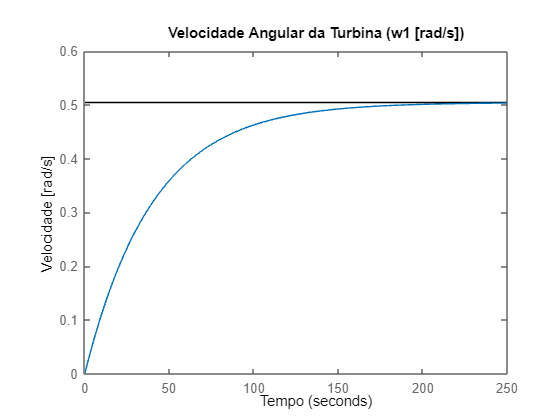

% comandos do matlab
figure, hold off,
step(Vv*Gv); % Resposta ao degrau de Vv m/s (15(t))
xlabel('Tempo'),ylabel('Velocidade [rad/s]');
title('Velocidade Angular da Turbina (w1 [rad/s])');

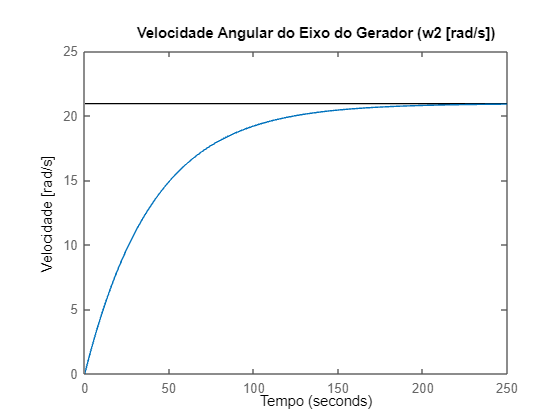


Gv2 = Gv/N;
step(Vv*Gv2); % Resposta ao degrau de Vv m/s (15(t))
xlabel('Tempo'),ylabel('Velocidade [rad/s]'),
title('Velocidade Angular do Eixo do Gerador (w2 [rad/s])');

### 1.8 Obtenha os gráficos de $T_{\textrm{ger}} \left(t\right)$ e $T_1 \left(t\right)$ para $V_v \left(t\right)$referente ao seu número I.

Temos que $T_{\textrm{ger}} \left(t\right)=158,7\omega_2 \left(t\right)$, logo, aplicando Laplace, obtemos:


$$T_{\textrm{ger}} \left(s\right)=158,7\Omega_2 \left(s\right)$$


Mas pela equação (3) temos $\omega_2 =\frac{\omega_1 }{N}$, e portanto:

$T_{\textrm{ger}} \left(s\right)=158,7\frac{\Omega_1 }{N}\left(s\right)$.

Ainda vimos que $G_v (s)=\frac{\Omega_1 (s)}{V_{\mathrm{v}} (s)}$, logo $T_{\textrm{ger}} \left(s\right)=\frac{158,7}{N}V_{\mathrm{v}} (s)G_v (s)$.

Finalmente:

$G_{T_{\textrm{ger}} } (s)=\frac{T_{\textrm{ger}} (s)}{V_{\mathrm{v}} (s)}=\frac{158,7}{N}G_v (s)$        (11).

Tendo $G_v (s)=\frac{\Omega_1 (s)}{V_{\mathrm{v}} (s)}$ e $G_1 (s)=\frac{\Omega_1 (s)}{{\;T}_1 (s)}$, então:

$G_{T_1 } (s)=\frac{{\;T}_1 (s)}{V_{\mathrm{v}} (s)}=\frac{\frac{\Omega_1 (s)}{G_1 (s)}}{\frac{\Omega_1 (s)}{G_v (s)}}=\frac{G_v (s)}{G_1 (s)}$        (12).

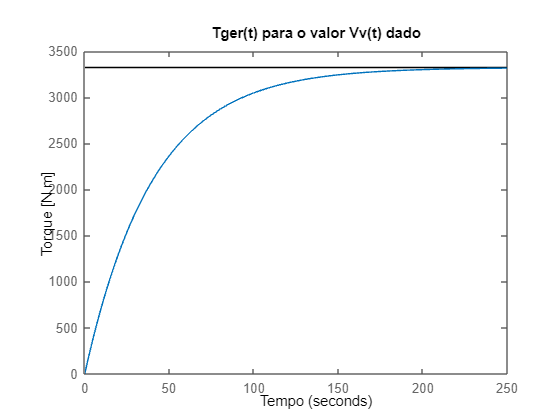

% comandos do matlab
GTger = (158.7/N)*Gv;
GT1 = Gv/G1;

figure;

step(Vv*GTger);
xlabel('Tempo'),ylabel('Torque [N.m]');

title('Tger(t) para o valor Vv(t) dado');

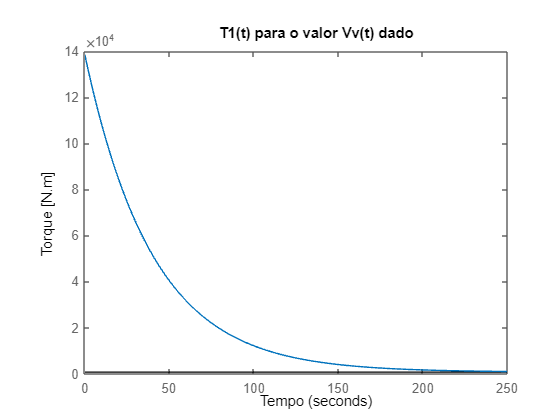



step(Vv*GT1);
xlabel('Tempo'),ylabel('Torque [N.m]');
title('T1(t) para o valor Vv(t) dado');

### 1.9 No instante $t_n$, a velocidade do vento aumenta de $V_v \;\left\lbrack m/s\right\rbrack$ para $V_{\textrm{vf}} \;\left\lbrack m/s\right\rbrack$ com aceleração constante de $a\;\left\lbrack m/s^2 \right\rbrack$ (na forma de uma rampa), sendo $t_n$, $V_v$, $V_{vf}$ e $a$ fornecidos pelo seu número I. Trace os gráficos das velocidades angulares da turbina, $\omega_1 \left(t\right)$, e do eixo do gerador, $\omega_2 \left(t\right)$, versus o tempo.

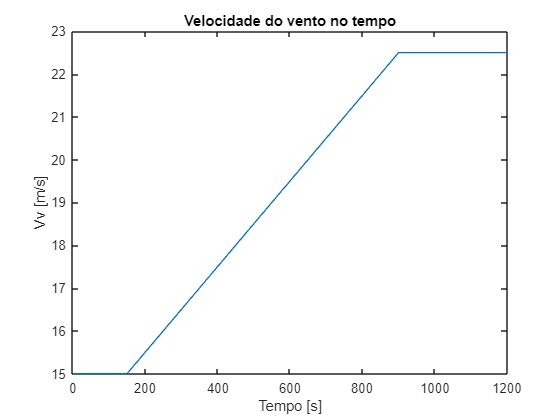

% comandos do matlab
t2_acl= (Vvf - Vv)/a;           % Tempo de aceleração

% Tempo de simulação
t1 = 1:1:tn;                    % Vetor de tempo de 0 a tn segundos com incrementos de 1 segundo
t2 = tn+1:1:3*tn+t2_acl;        % Vetor de tempo de tn a 3*tn + t2_max segundos com incrementos de 1 segundo
t = [t1, t2];                   % Concatenação dos vetores de tempo

% Funcao que representa a velocidade do vento no tempo
u1 = Vv * ones(size(t1));       % Velocidade do vento constante até tn
u2 = Vv + a*(t2-tn);            % Velocidade do vento acelerando após tn
u2(u2 > Vvf) = Vvf;             % Limita a velocidade do vento a Vvf após atingir Vvf
u = [u1, u2];                   % Concatenação dos vetores de vel. do vento
plot(t, u);
xlabel('Tempo [s]');
ylabel('Vv [m/s]');
title('Velocidade do vento no tempo');

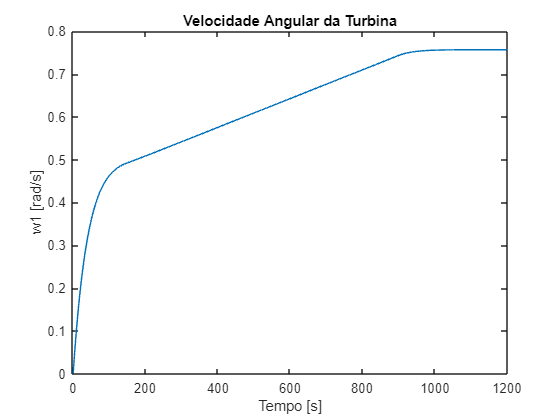


% Simulação dos modelos no domínio do tempo
w1 = lsim(Gv, u, t);    % Resposta de w1
w2 = lsim(Gv2, u, t);   % Resposta de w2

% Gráficos
figure;
plot(t, w1);
xlabel('Tempo [s]');
ylabel('w1 [rad/s]');
title('Velocidade Angular da Turbina');

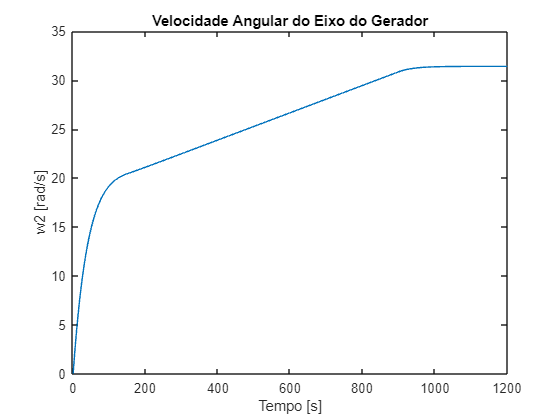

plot(t, w2);
xlabel('Tempo [s]');
ylabel('w2 [rad/s]');
title('Velocidade Angular do Eixo do Gerador');